clc;
close all;
clear variables;

## Creating a datastore for my images

folder_name = fullfile(pwd, 'data');
imds = imageDatastore(folder_name, 'LabelSource',"foldernames");

### Label data 

Get label from filename

imds.Labels = char(imds.Labels); % turn labes to char
N = length(imds.Files);
for i = 1:N
    filename = imds.Files{i}(length(folder_name) + 1:end);
    left_parenth_index = find(filename == ' ');
    label = filename(2:left_parenth_index - 1);
    if strcmp(label, 'prazna')
        label = 'E';
    elseif strcmp(label,'pune')
        label = 'F';
    end
    imds.Labels{i} = label;
end

Only full balls

full_ball_imds = subset(imds, [imds.Labels{:}] == 'F');

## Preprocessing images

target_size = [600, 600];
final_size = [600, 600];
sigma_r = 650;
sigma_s = 5;

%full_ball_imds = shuffle(full_ball_imds);

preprocessed_imds = transform(full_ball_imds, @(x) imresize(x, target_size));

preprocessed_imds = transform(preprocessed_imds, @(x) imresize(x, final_size));

preprocessed_imds = transform(preprocessed_imds, @(x) rgb2gray(x));

% preprocessed_imds = transform(preprocessed_imds, @(x) imbilatfilt(x, sigma_r, sigma_s));

filtered_imds = preprocessed_imds;

% preprocessed_imds = transform(preprocessed_imds, @(x) edge(x, 'Canny'));

preprocessed_imds = transform(preprocessed_imds, @(x)adaptive_binarization(x));

### Display preprocessed images

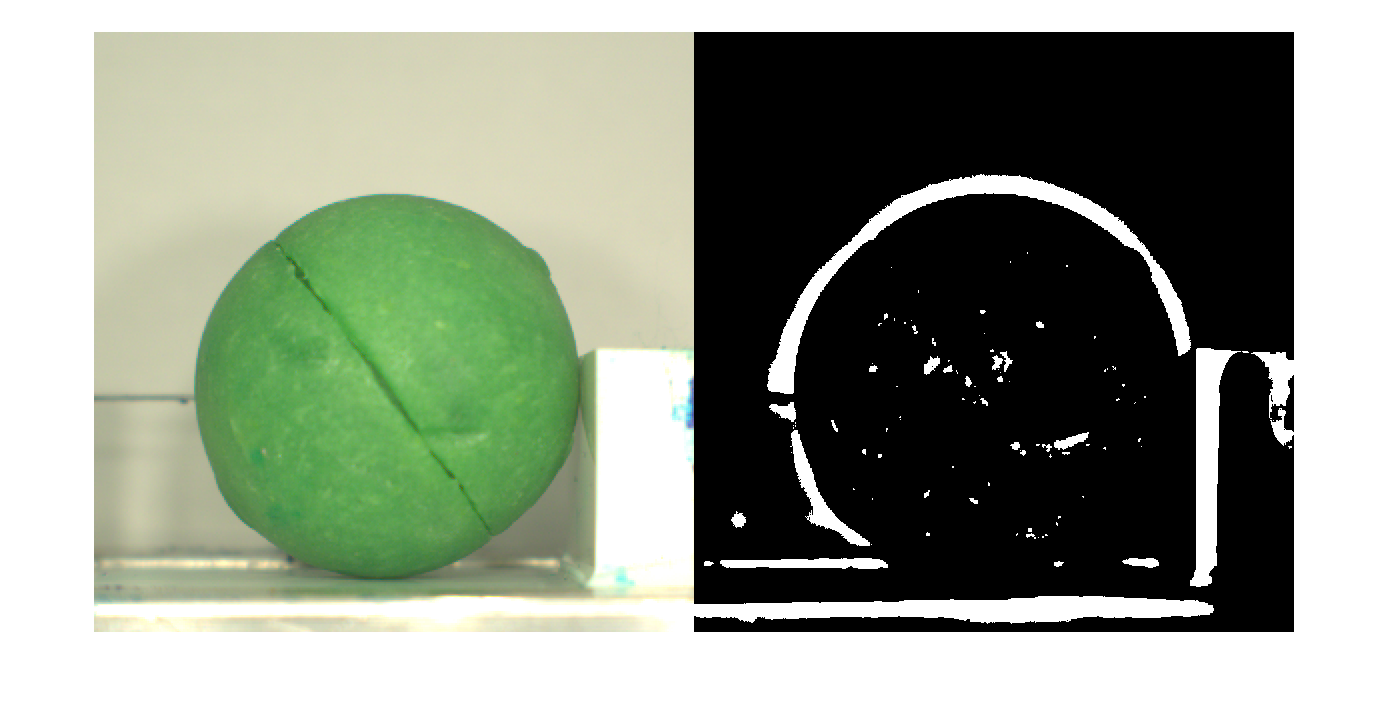

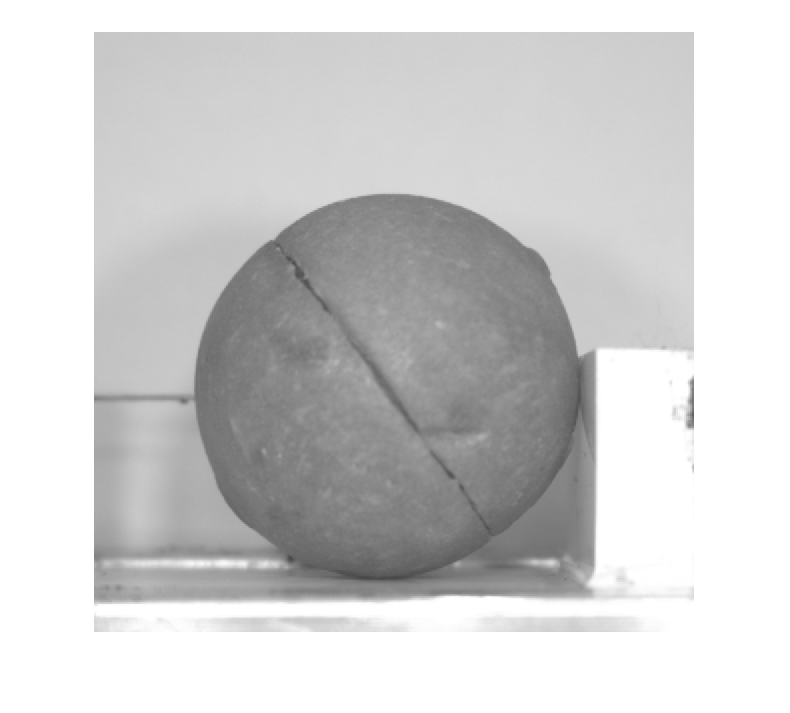

for i=1:1
    figure();
    original = preview(preprocessed_imds.UnderlyingDatastore);
    filtered = preview(filtered_imds);
    canny = preview(preprocessed_imds);
    imshowpair(original, canny, 'montage')
    figure();
    imshow(filtered)
end

[https://www.mathworks.com/help/images/detecting-a-cell-using-image-segmentation.html](https://www.mathworks.com/help/images/detecting-a-cell-using-image-segmentation.html)

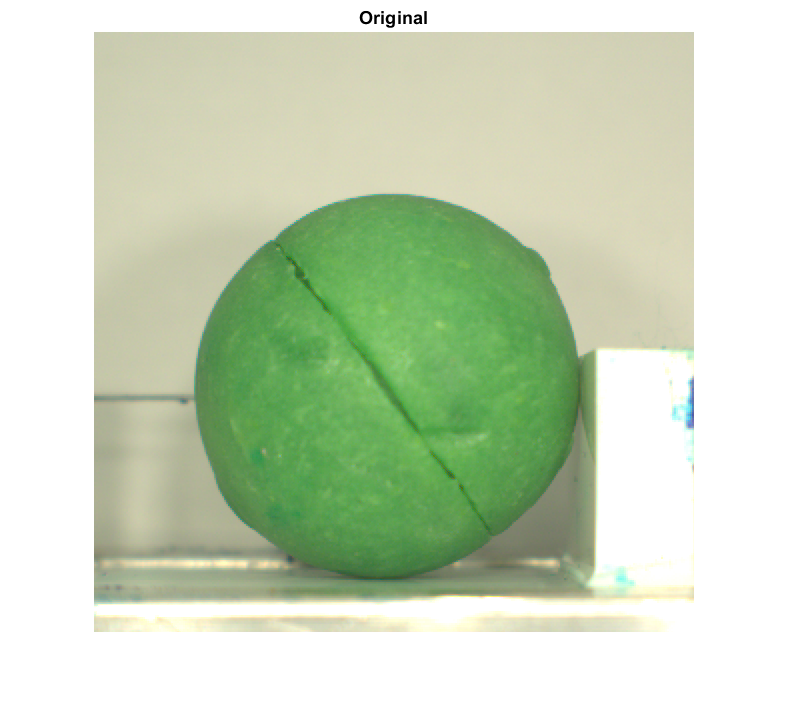

original = preview(preprocessed_imds.UnderlyingDatastore);
figure();
imshow(original)
title("Original")

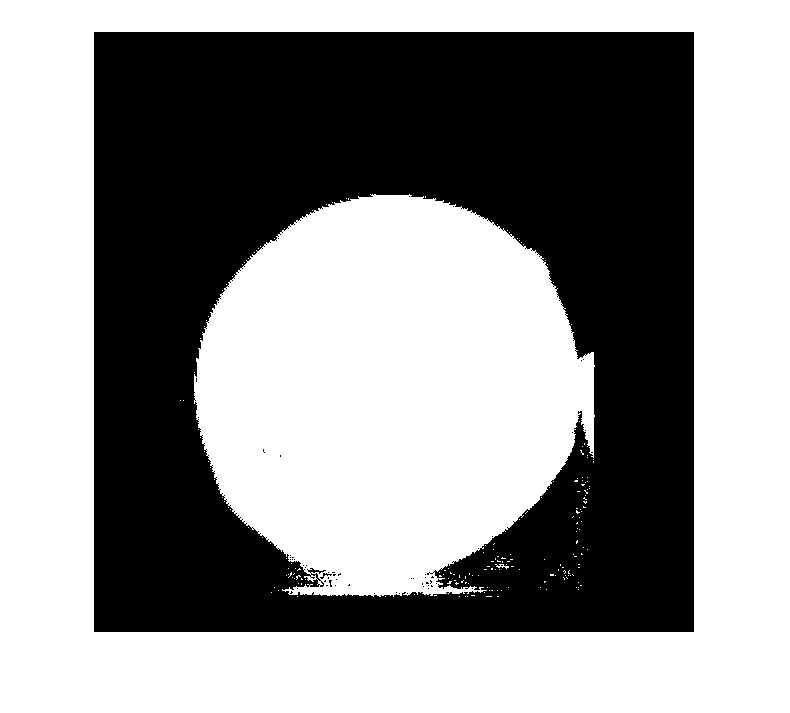

lab = rgb2lab(original);
hsv = rgb2hsv(original);
ntsc = rgb2ntsc(original);
xyz = rgb2xyz(original);
ycbcr = rgb2ycbcr(original);
img = lab;

X = reshape(img, size(original, 1) * size(original, 2), size(original, 3));
idx = kmeans(double(X), 2);
mask = reshape(idx, [size(original, 1), size(original, 2)]) - 1;
if mask(1, 1) == 1
    mask = ~mask;
end
figure();
imshow(mask)